# LAB 10: LEAD COMPENSATOR DESIGN

%---------------------------------------
% Fill in your student Name and ID.
Students.Name = 'Seyed Yazdan Zinati';
Students.ID = '260928077';
%---------------------------------------

## **0. Objectives**

In this lab, we will use Bode plot to design a lead compensation controller for a system.

## **1. Bode Plot, Gain Margin, and Phase Margin**

Consider the following open-loop transfer function:


$$G(s) = \displaystyle \frac{s+2}{(2s+1)(s^2 -0.5 s + 1)}$$


## *Question 1 (1 mark)*

Plot the Bode of $G(s)$ (help `bodeplot`).

% Define G
s = tf('s');
G = [(s + 2) / ((2*s + 1) * (s^2 - 0.5*s + 1))]

G =
 
        s + 2
  -----------------
  2 s^3 + 1.5 s + 1
 
Continuous-time transfer function.



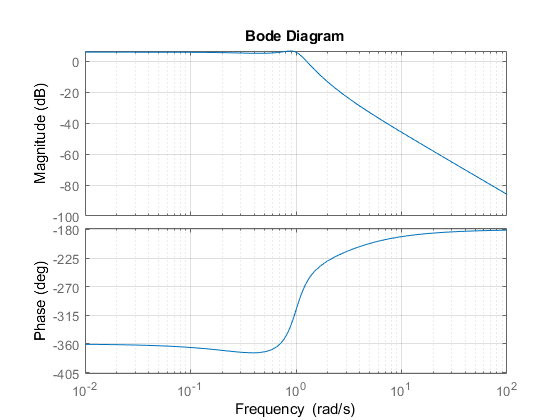


bodeplot(G)

grid on

In MATLAB, we can use `margin` to calculate the gain margin, `Gm`, phase margin, `Pm`, and associated frequencies `Wgm` and `Wpm` of SISO open-loop models. The gain and phase margin of a system `sys` indicates the relative stability of the closed-loop system formed by applying unit negative feedback to `sys`.

The gain margin is the amount of gain increase or decrease required to make the loop gain unity at the frequency `Wgm` where the phase angle is $-180$ (modulo $360$). In other words, the gain margin is $\displaystyle \frac{1}{g}$ if $g$ is the gain at the $180$ phase frequency. Similarly, the phase margin is the difference between the phase of the response and $180$ when the loop gain is 1.0. The frequency `Wpm` at which the magnitude is 1.0 is called the *unity-gain frequency* or *gain crossover frequency*.

**Note:** It is generally found that gain margins of three or more combined with phase margins between 30 and 60 degrees result in reasonable trade-offs between bandwidth and stability.

We use this function as follows: `[Gm,Pm,Wgm,Wpm] = margin(sys)`. `Wgm` is the frequency where the gain margin is measured, which is a -180 degree phase crossing frequency. `Wpm` is the frequency where the phase margin is measured, which is a 0dB gain crossing frequency. These frequencies are expressed in rad/s is the unit specified in the property of `sys`. When `sys` has several crossovers, `margin` returns the smallest gain and phase margins and corresponding frequencies. For more information about `margin(sys)`.

## *Question 2 (1 mark)*

Find the Gain Margin, Phase Margin and the corresponding frequencies for $G(s)$. (help `margin`).

[Gm, Pm, Wgm, Wpm] = margin(G);


Pm

Pm = -82.7056

Gm

Gm = Inf

## *Question 3 (1 mark)*

Determine whether the open-loop system is stable or not? Based on the values of the GM and PM, What can you say about the stability of the closed-loop system? Justify your answer.

pole(G)

ans =    0.2500 + 0.9682i
   0.2500 - 0.9682i
  -0.5000 + 0.0000i



% Open-loop stability
% the system has poles in the Open Right Hand Plane 
% so the open-loop system is unstable 

% Closed-loop stability
% Gm > 0 and Pm < 0 so the closed loop system is unstable

## *2. Lead Compensator Design*

Let $G_{cl}(s)$ be the unity feedback closed-loop transfer function of $G(s)$ and could be found as follows:


$$ G_{cl}(s) = \displaystyle \frac{C_{Lead}(s) G(s)}{1 + C_{Lead}(s) G(s)} $$


A first order phase-lead compensator has the form given below:


$$ C_{Lead} = K \displaystyle \frac{1 + T s}{1 + \alpha T s}, \quad
\alpha < 1, \quad K = K_c \alpha $$


The open-loop transfer function of the compensated system is


$$G_{ol}(s) = K \displaystyle \frac{1 + T s}{1 + \alpha T s} G(s)$$


We want to design a lead compensator such that the following conditions are satisfied:

- Steady-state error to a step input $\leq 0.05$.

- Phase margin $\geq 45$.

The first step in the lead design is to provide the required static position error constant. Define $G_1(s)$ as follows:


$$G_1(s) = K G(s)$$


## *Question 4 (1 mark)*

Find the value of $K$ such that the steady state conditions are satisfied.

K = 9.5 % (Caluculated)

K = 9.5000

With this value of $K$, the compensated system will satisfy the steady-state requirement. Now we shall plot the Bode plot of $G_1(s)$.

## *Question 5 (1 mark)*

Draw the Bode plot of $G_1(s)$ and find the GM, PM, and corresponding frequencies. (Draw the Bode plot of $G(s)$ again to see the difference)

% Draw the Bode plot
G1 = K * G

G1 =
 
     9.5 s + 19
  -----------------
  2 s^3 + 1.5 s + 1
 
Continuous-time transfer function.



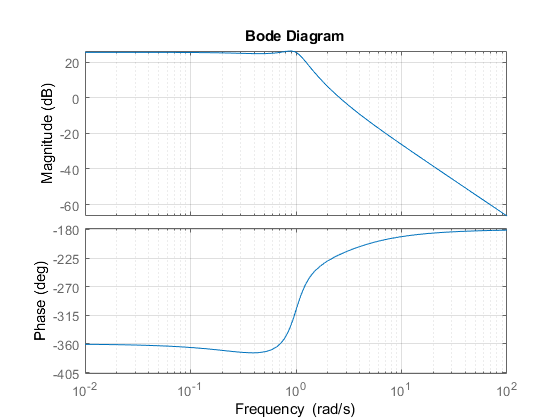


bode(G1)
grid on



% Determine the gain and phase margin of G1 = KG (from Bode plot)
[Gm, Pm, Wgm, Wpm] = margin(G1);


Pm

Pm = -39.4443

Gm

Gm = Inf

The phase-lead compensator will add positive phase to our system over the frequency range $\displaystyle \frac{1}{a T}$ and $\displaystyle \frac{1}{T}$, which are called the corner frequencies.

## *Question 6 (2 marks)*

Based on the values of the GM and PM and the corresponding frequencies you found in Question 5, design the lead compensator that satisfies the conditions given in this part. Write the final lead compensator as a transfer function.

Hint: `sin()` in `MATLAB` uses radian as the input argument. For input arguments in degree use `sind()`.

% The desired phase margin is 45
PMd = 45;   

% Determine alpha
alpha = (1 - sind(PMd - Pm + 1)) / (1 + sind(PMd - Pm + 1))

alpha = 0.0016


% Determine the crossover frequency (from bode plot)
mag_cross_db = 10 * log10(alpha)

mag_cross_db = -28.0075


% from the bode plot at M = -28: 
w_cross = 11.2 

w_cross = 11.2000


% Write the final lead compensator transfer function
T = 1 / (w_cross * sqrt(alpha))

T = 2.2447


CLead = K * (1 + T * s) / (1 + alpha * T * s)

CLead =
 
  21.32 s + 9.5
  --------------
  0.003551 s + 1
 
Continuous-time transfer function.



## *Question 7 (1 mark)*

Produce the Bode diagram of the lead compensator you found in Question 6.

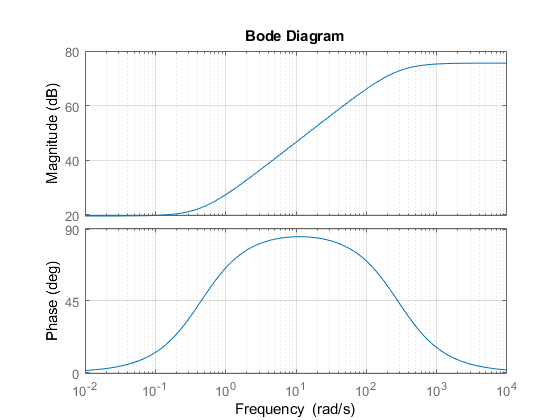

% Draw the Bode plot

bode(CLead)
grid on

## *Question 8 (1 mark)*

Produce the Bode diagram of the transfer function $G_{Lead}(s) = C_{Lead}(s) G(s)$. Check whether the specifications are satisfied or not (use `margin` to check the GM and PM).

% Define Gcl
GLead  = CLead * G

GLead =
 
              21.32 s^2 + 52.15 s + 19
  -------------------------------------------------
  0.007103 s^4 + 2 s^3 + 0.005327 s^2 + 1.504 s + 1
 
Continuous-time transfer function.



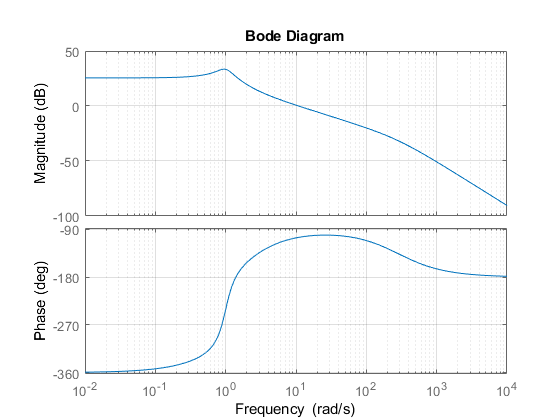


% Draw Bode Plot
bode(GLead)
grid on


[GmLead, PmLead, WgmLead, WpmLead] = margin(GLead);
PmLead

PmLead = 75.0343

GmLead

GmLead = 0.0455


if PmLead >= 45
    disp('The phase margin requirements are satisfied');
else
    disp(['The phase margin obtained ' num2str(PmLead) ' is less than required 45 degrees.']);
end

The phase margin requirements are satisfied


## *Question 9 (1 mark)*

Plot the step response of the closed-loop system $G_{cl}(s)$. (help `step`) .

Gcl = GLead / (1 + GLead)

Gcl =
 
                0.1515 s^6 + 43.02 s^5 + 104.5 s^4 + 70.34 s^3 + 99.83 s^2 + 80.72 s + 19
  ------------------------------------------------------------------------------------------------------
  5.045e-05 s^8 + 0.02841 s^7 + 4.152 s^6 + 43.06 s^5 + 110.6 s^4 + 74.36 s^3 + 102.1 s^2 + 83.72 s + 20
 
Continuous-time transfer function.



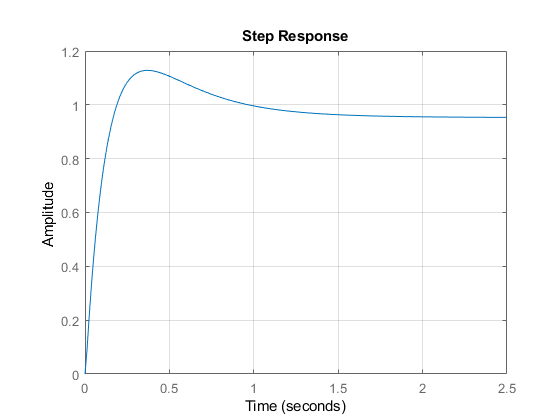


step(Gcl)
grid on